**Submission: **Convert this document to a pdf file for submission

**提交**：将本文档转化为pdf文件提交到gradescope

**PART 1    Simple Introdution**

(10 points)1. $\mathrm{y}=e^{x+x^2 }$ and $\mathrm{y}=\sin \left(x\right)\cos \left(x\right)$,x is from -5 to 5. Please plot the figure in a **1*2 **figure .(Hint: use *subplot. *Both numerical method and symbolic method is ok)

定义$\mathrm{y}=e^{x+x^2 }$ 和 $\mathrm{y}=\sin \left(x\right)\cos \left(x\right)$，x的定义域为[-5.5]，并在在**1*2**的图中画出两个函数。（提示：使用*subplot*来画1*2的图。数值法和符号法都可行）

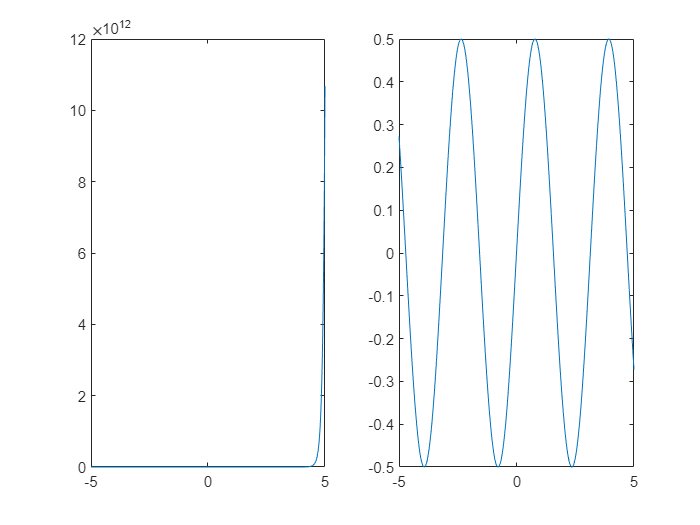

subplot(1,2,1)

x = -5:0.00001:5;
y = exp(x + x.^2);

plot(x,y)


subplot(1,2,2)

x = -5:0.00001:5;
y = sin(x).*cos(x);

plot(x,y)

(8 points)2. Let a =17.2, b = 4. Please calculate the following formulas and **show** the results.

令a =17.2, b = 4。 请计算出c与d的值并展示出结果。


$$c=\;\sqrt[3]{a+9\ldotp 8}$$



$$d=100\cdot \sqrt{5b+16}$$


a = 17.2;
b = 4;

c = (a + 9.8).^(1/3);
d = 100*(5*b + 6).^(1/2);

c

c = 3

d

d = 509.9020

(10 points)3. Please solve the following equations.

请求解以下方程组


$$\left\lbrace \begin{array}{c}
3x+2y-z=10\\
-x+3y+2z=5\\
x-y-z=-1
\end{array}\right.$$


a. changing to the matrix form.

用矩阵表示该方程组系数

b. using matrix operation to solve. (**Hint**:use A/B or A\B)

请使用矩阵方法求解该方程组

syms x y z;

f1 = [ 3*x + 2*y - z == 10
      -x + 3*y + 2*z ==  5
           x - y - z == -1];

[a,b] = equationsToMatrix(f1,[x y z]);

matrix = a

$$matrix = \left(\begin{array}{ccc} 3 & 2 & -1\\ -1 & 3 & 2\\ 1 & -1 & -1 \end{array}\right)$$

solution = a\b

$$solution = \left(\begin{array}{c} -2\\ 5\\ -6 \end{array}\right)$$

(12 points) 4. Find the prime number between 1 and 100 **by using loop and branching**. (*primes* is not allowed)

找到1到100之间的质数并显示结果。（函数*primes*不被允许使用）

primes = [];
for i = 2:99

    k = 1;

    for j = 2:(i - 1)

        if mod(i,j) == 0

            k = 0;
            break

        end

    end

    if k == 1

        primes = [primes,i];

    end
 
end

disp(primes)

     2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97



**PART 2     File Loading and Analysis** 

(24 points)5. Fetching external data( Do not change the value you obtain)

外部数据获取（不要修改获取的数据的值）

a. Load file Array.mat, display vector and matrix

读入Array.mat，并显示其中的两个变量vector及matrix

b. Assign the 3rd, 6th, 9th, and 12th digits to a vectorA and display vectorA

将vector中第3、6、9、12个数赋给vectorA，并显示结果

c. Assign vector to the vectorB, change the 4th number in the vectorB to 12, and display vectorB

将vector赋值给vectorB，将vectorB中的第4个数修改为12后显示结果

d. Assign rows 5, 6, and 7 of matrix to matrixA and display matrixA

将matrix的第5，6，7行赋予matrixA，并显示结果

e. Assign rows 1,2, and columns 2,3 of matrix to a matrixB and display matrixB

将matrix的第1，2行及第2，3列赋予matrixB，并显示结果 

f. Find the location of a value less than 3 in the matrix

找出matrix中小于3的值的位置

% Load file Array.mat, display vector and matrix
data = load("Array.mat");

disp(data.vector)

     4    -4     3    -3     2     2    -1     0    -4     4     0     5



disp(data.matrix)

    -1     2    -4     5     4
    -2    -3     4    -2    -3
     3     3     5    -4    -2
    -4     3     1    -1    -4
     3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4
    -3     4    -2     2    -4
     1    -1     0     2     4
     0     2    -4     0     4



% Assign the 3rd, 6th, 9th, and 12th digits to a vectorA and display vectorA
vectorA = [data.vector(3), data.vector(6), data.vector(9), data.vector(12)];

disp(vectorA)

     3     2    -4     5



% Assign vector to the vectorB, change the 4th number in the vectorB to 12, 
% and display vectorB
vectorB = data.vector;
vectorB(4) = 12;

disp(vectorB)

     4    -4     3    12     2     2    -1     0    -4     4     0     5



% Assign rows 5, 6, and 7 of matrix to matrixA and display matrixA
matrixA = data.matrix(5:7, :);

disp(matrixA)

     3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4



% Assign rows 1,2, and columns 2,3 of matrix to a matrixB and display matrixB
matrixB = data.matrix(1:2, 2:3);

disp(matrixB)

     2    -4
    -3     4



% Find the location of a value less than 3 in the matrix
[r,c] = size(data.matrix);
k = 1;

for i = 1:r

    for j = 1:c

        if data.matrix(i,j) < 3

            location = [i,j];
            fprintf('location %i: (%i,%i)\n', k, location(1), location(2))
            k = k + 1;

        end

    end


end

location 1: (1,1)
location 2: (1,2)
location 3: (1,3)
location 4: (2,1)
location 5: (2,2)
location 6: (2,4)
location 7: (2,5)
location 8: (3,4)
location 9: (3,5)
location 10: (4,1)
location 11: (4,3)
location 12: (4,4)
location 13: (4,5)
location 14: (5,2)
location 15: (5,4)
location 16: (5,5)
location 17: (6,3)
location 18: (6,4)
location 19: (7,1)
location 20: (7,2)
location 21: (7,5)
location 22: (8,1)
location 23: (8,3)
location 24: (8,4)
location 25: (8,5)
location 26: (9,1)
location 27: (9,2)
location 28: (9,3)
location 29: (9,4)
location 30: (10,1)
location 31: (10,2)
location 32: (10,3)
location 33: (10,4)


(24 points)6. Load *data.xlsx ，*fix the data table and display (Hint: *readtable/importdata *may be helpful)

读入excel数据，补全数据表(计算第三列)并输出

output formal example：

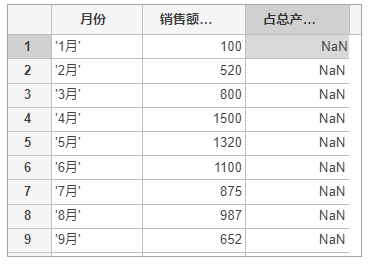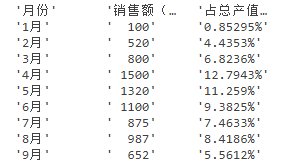

table = readtable("data.xlsx","VariableNamingRule","preserve");

for i = 1:13

    table{i,3} = table{i,2}./11724;

end

disp(table)

        月份         销售额（万元）    占总产值百分比
    _____________    ____________    ____________

    {'1月'      }         100         0.0085295  
    {'2月'      }         520          0.044353  
    {'3月'      }         800          0.068236  
    {'4月'      }        1500           0.12794  
    {'5月'      }        1320           0.11259  
    {'6月'      }        1100          0.093825  
    {'7月'      }         875          0.074633  
    {'8月'      }         987          0.084186  
    {'9月'      }         652          0.055612  
    {'10月'     }        1300           0.11088  
    {'11月'     }        1600           0.13647  
    {'12月'     }         970          0.082736  
    {'销售总额：'}       11724                 1  



(16 points)7.

a.load *picture.jpg* and display this picture 

加载图片文件（*picture.jpg*）并显示

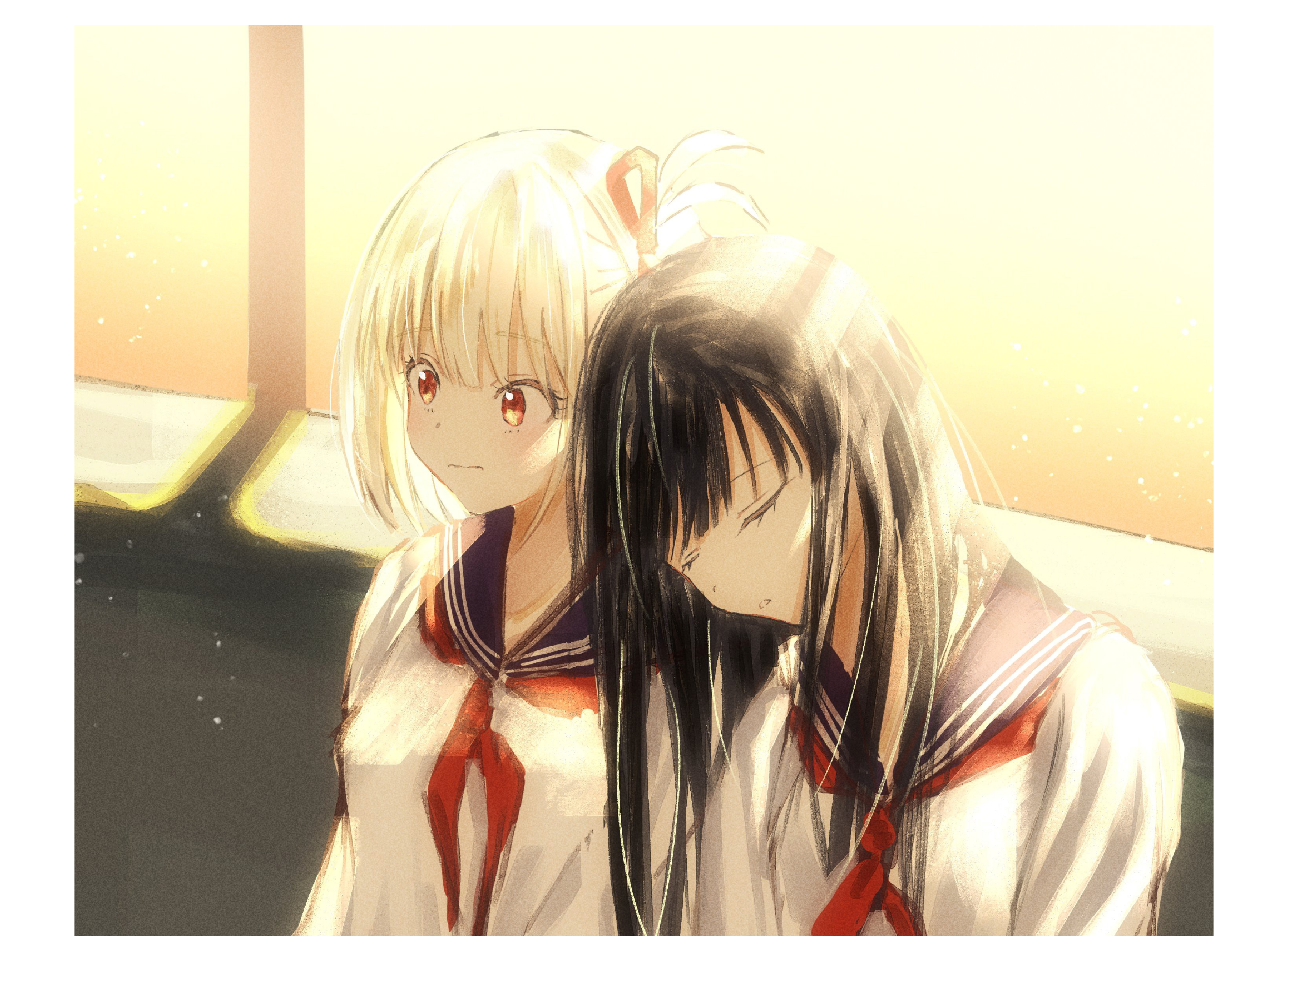

Image = imread("picture.jpg");

subplot(1,1,1)

imshow(Image)

b. load *TheySay.mp3*, sound  and display sampling frequency. (Hint:What is the sampling frequency? Search on the Internet)

载入声音文件（*TheySay.mp3*），播放并输出采样频率

[y,Fs] = audioread("TheySay.mp3");

sound(y,Fs);

disp(Fs)

       44100

